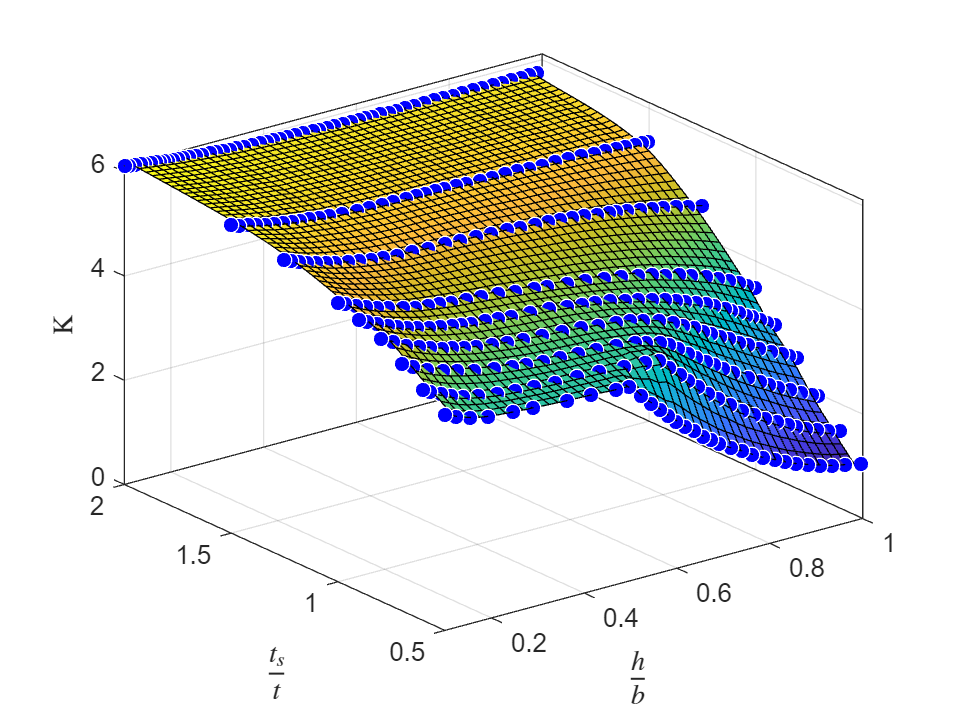

clear

bm=90636*1.5;
diameter=1.8; %meters
E=72e9;
flength=12;
density=2700;
load("data.mat");

[kskindirect,~]=generate_luca(xdata,ydata,zdata);


%kval=k(h/b,ts/t)

nstringrange=[50,90]

nstringrange =     50    90


nframerange=[20,30]

nframerange =     20    30


trange=[0.001,0.0001,0.002]

trange =     0.0010    0.0001    0.0020


tsrange=[0.001,0.001,0.005]

tsrange =     0.0010    0.0010    0.0050


hrange=[0.01,0.01,0.05]

hrange =     0.0100    0.0100    0.0500



phi = linspace(0,360,36);

% Letting shear yield stress = max shear stress
% then find skin thickness
%shear_ys = ; % shear yield stress (MPa)
%skin_t = ; % skin thickness (m)
% Considering up, right and anti-clockwise positive

% Point load on ring
Q = 90130*1.5; % (N)
P = 2413*1.5; % (N)
T = 4718*1.5; % (Nm)

Totsflow = Q*sind(phi)/(pi*diameter/2) + P*cosd(phi)/(pi*diameter/2) + (T + P*(diameter/2))/(2*pi*(diameter/2)^3);
if (max(Totsflow)<abs(min(Totsflow)))
    q_total = min(Totsflow)
else
    q_total = max(Totsflow)
end

q_total = 4.9966e+04


iteration=zeros(int64((nstringrange(2)-nstringrange(1)+1)*(nframerange(2)-nframerange(1)+1)*((hrange(3)-hrange(1))/hrange(2)+1)*((trange(3)-trange(1))/trange(2)+1)*((trange(3)-trange(1))/trange(2)+1)),12);

c=0;

tic

for nframes=nframerange(1):nframerange(2)
    framemass=lframemass(nframes);
    for nstring=nstringrange(1):nstringrange(2) 
        for t=trange(1):trange(2):trange(3)
            for ts=tsrange(1):tsrange(2):tsrange(3) %t:0.005:1.8*t
                for h=hrange(1):hrange(2):hrange(3) %(0.2*diameter*pi)/nstring
                    c=c+1;
                    iteration(c,1)=nstring;
                    iteration(c,2)=nframes;
                    iteration(c,3)=t;
                    iteration(c,4)=ts;
                    iteration(c,5)=h;
                    iteration(c,6)=1.8*ts*h*sum(((diameter/2)*sin(linspace(0,2*pi,nstring))).^2)+pi*t*(diameter/2)^3;
                    iteration(c,7)=bm*(diameter/2)/iteration(c,6);
                    iteration(c,8)=q_total/t;
                    iteration(c,9)=pi^2*E*(ts*(h^3)/12+0.4*ts*(h^3)/2)/(1.8*h*ts*((12/nframes)^2)); %(((0.4*h+0.5*ts)*(h+ts)^3-(0.4*h-0.5*ts)*(h-ts)^3)/12)
                    iteration(c,10)=kskinshear(12/nframes,3.14*diameter/nstring,t)*E*(t/(3.14*diameter/nstring))^2;
                    if h/(diameter*3.14/nstring) < 0.1 || h/(diameter*3.14/nstring) > 1 ||  ts/t < 0.5 || ts/t > 2
                        continue
                    end
                    iteration(c,11)=kskindirect(h/(diameter*3.14/nstring),ts/t)*E*(t/(3.14*diameter/nstring))^2;
                    iteration(c,12)=density*flength*pi*((diameter/2)^2-(diameter/2-t)^2)+1.8*h*ts*nstring*flength*density+framemass;
                    if iteration(c,7)<iteration(c,9)&iteration(c,7)/iteration(c,11)+(iteration(c,7)/iteration(c,10))^2<0.99;
                        iteration(c,13)=1;
                    else
                        iteration(c,13)=0;
                    end
                end
            end
        end
    end
end

Solving problem using fmincon.

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.


Solving problem using fmincon.




toc

Elapsed time is 147.089544 seconds.



solution=iteration(iteration(:,13)==1,:);
[val,index]=min(solution(:,12));
best=solution(index,:)

best = 1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.3898    0.4542    0.6991    0.5022    1.0108    0.0000    0.0000



[y,sol]=lframemass(best(2))

Solving problem using fmincon.

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



y = 18.3218

sol = struct with fields:
    b: 0.0100
    h: 0.0200


function [y,sol]=lframemass(nframe);

E=72e9;
diameter=1.8;
bm=90636*1.5;
cf=0.0000625;
density=2700;
flength=12;

I=(cf*bm*diameter^2)/(flength*E/nframe);

framemass = optimproblem('ObjectiveSense','min');

bframe = optimvar('b','LowerBound',0.01,'UpperBound',0.1);
hframe = optimvar('h','LowerBound',0.02,'UpperBound',0.1);

framemass.Constraints.cons1 = I/(hframe^3/12+bframe*hframe^2/2)>= 0.001;

framemass.Objective = I*(2*bframe+hframe)/(hframe^3/12+bframe*hframe^2/2);

sol0.b=0.05;
sol0.h=0.05;

sol=solve(framemass,sol0);

t=I/(sol.h^3/12+sol.b*sol.h^2/2);

y=density*nframe*pi*diameter*0.001*(2*sol.b+sol.h);

end

function y=kskinshear(a,b,t)
diameter=1.8;
y=2.5*(b/sqrt(t*diameter/2))/(0.058*a/b+0.81)-2;
end